**Sobel Convolution**

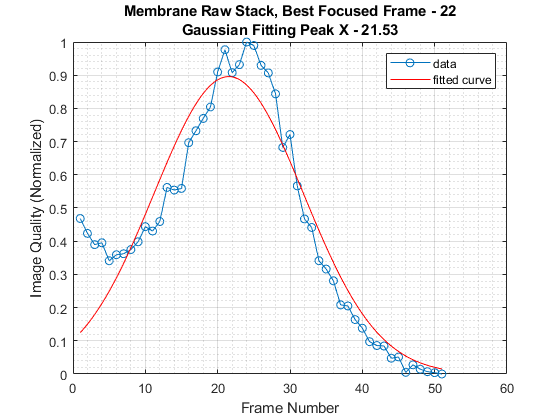

% Membrane
file_mem = 'X:/volume_scan/23-Apr-2018/membrane_psf_561.tif';
best_focus_at = 22;
num_imgs_mem = numel(imfinfo(file_mem));
x_arr_mem = (1:1:num_imgs_mem);
y_arr_mem = zeros(1, num_imgs_mem);
raw_img = cell(num_imgs_mem);
for i = 1:num_imgs_mem
    raw_img{i} = imread(file_mem, i);
end



y_arr_mem_raw = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = raw_img{i};
    y_arr_mem_raw(i) = convolve_sobel(filtered_img);
end
y_arr_mem_raw = normalize(y_arr_mem_raw, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_raw', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_raw, '');

plot(f_mem, x_arr_mem, y_arr_mem_raw, '-o');
title(sprintf(['Membrane Raw Stack, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

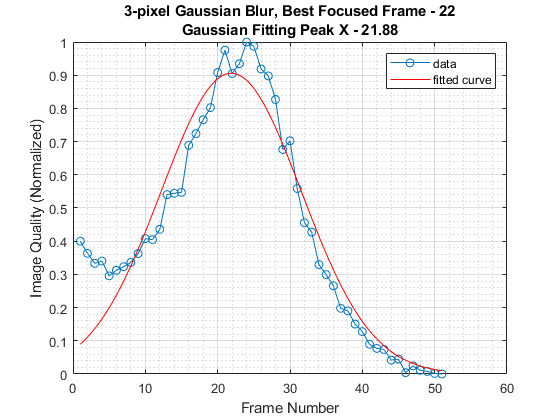




y_arr_mem_gau = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = imgaussfilt(raw_img{i},'FilterSize',3);
    y_arr_mem_gau(i) = convolve_sobel(filtered_img);
end
y_arr_mem_gau = normalize(y_arr_mem_gau, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_gau', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_gau, '');

plot(f_mem, x_arr_mem, y_arr_mem_gau, '-o');
title(sprintf(['3-pixel Gaussian Blur, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

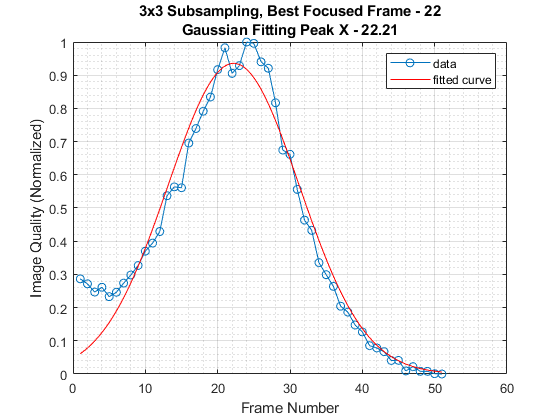



y_arr_mem_sub = zeros(1, num_imgs_mem);
for i = 1:num_imgs_mem
    filtered_img = imresize(imresize(raw_img{i},0.333,'box'),3,'box');
    y_arr_mem_sub(i) = convolve_sobel(filtered_img);
end
y_arr_mem_sub = normalize(y_arr_mem_sub, 'range');
f_mem = fit(x_arr_mem', y_arr_mem_sub', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem, y_arr_mem_sub, '');

plot(f_mem, x_arr_mem, y_arr_mem_sub, '-o');
title(sprintf(['3x3 Subsampling, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

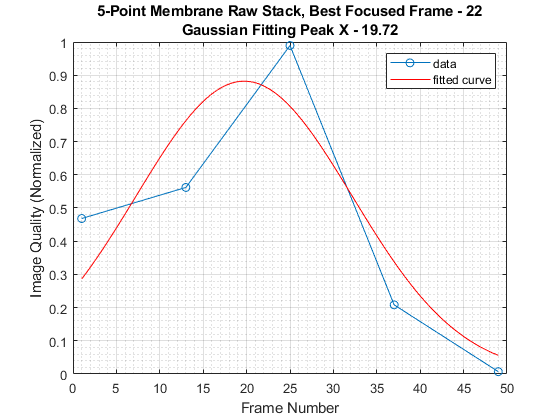


% ============ 5-point sampling ==============
x_arr_mem_raw = x_arr_mem(1:12:end);

y_arr_mem_raw = y_arr_mem_raw(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_raw', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_raw, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_raw, '-o');
title(sprintf(['5-Point Membrane Raw Stack, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

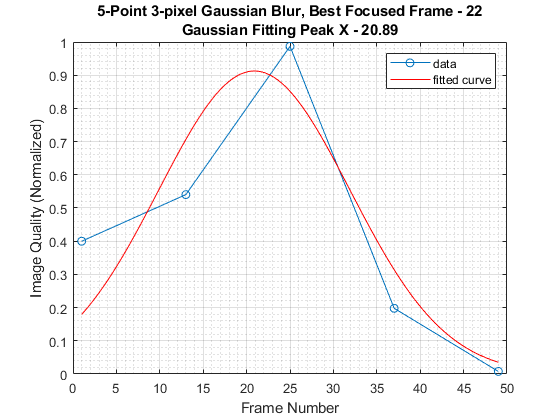


y_arr_mem_gau = y_arr_mem_gau(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_gau', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_gau, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_gau, '-o');
title(sprintf(['5-Point 3-pixel Gaussian Blur, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor

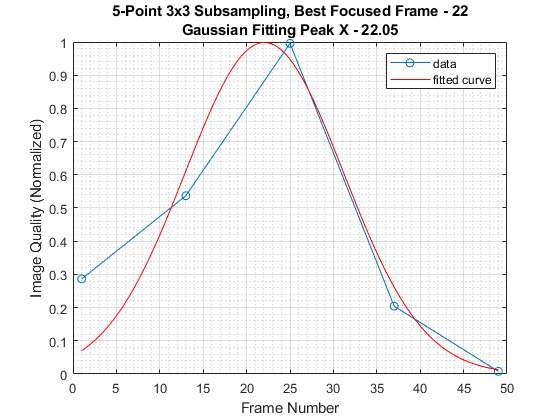


y_arr_mem_sub = y_arr_mem_sub(1:12:end);
f_mem = fit(x_arr_mem_raw', y_arr_mem_sub', 'gauss1');
[peak_x_mem, peak_y_mem] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_sub, '');
plot(f_mem, x_arr_mem_raw, y_arr_mem_sub, '-o');
title(sprintf(['5-Point 3x3 Subsampling, Best Focused Frame - %d\n' ...
    'Gaussian Fitting Peak X - %.2f'], best_focus_at, peak_x_mem));
xlabel('Frame Number');
ylabel('Image Quality (Normalized)');
grid on
grid minor



tic
y_arr_mem_ben = zeros(1, 5);
j = 1;
for i = 1:12:50
    ben_im = imresize(imresize(raw_img{i}, 0.333, 'box'), 3, 'box');
    y_arr_mem_ben(j) = convolve_sobel(ben_im);
    j  = j +  1;
end
y_arr_mem_ben = normalize(y_arr_mem_ben, 'range');
f_mem = fit(x_arr_mem_raw', y_arr_mem_ben', 'gauss1');
[p_x, p_y] = peak_in_gaussian(x_arr_mem_raw, y_arr_mem_ben, '');
toc

Elapsed time is 0.266728 seconds.


% Nucleus
% disp('Nucleus');
% file_nuc = 'X:/volume_scan/23-Apr-2018/nucleus_psf_488.tif';
% num_imgs_nuc = numel(imfinfo(file_nuc));
% x_arr_nuc = (1:1:num_imgs_nuc);
% y_arr_nuc = zeros(1, num_imgs_nuc);
% for i = 1:num_imgs_nuc
%     raw_img = imread(file_nuc, i);
%     filtered_img = imgaussfilt(raw_img, 'FilterSize', 3);
%     %filtered_img = imresize(imresize(raw_img,0.5,'box'),2,'box');
%     y_arr_nuc(i) = convolve_sobel(filtered_img);
% end
% f = fit(x_arr_nuc', y_arr_nuc', 'gauss1');
% plot(f, x_arr_nuc, y_arr_nuc, '-o');
% 
% 
% [peak_x_nuc, peak_y_nuc] = peak_in_gaussian(x_arr_nuc, y_arr_nuc, '')



% file_mem = '\\nsrg.cs.unc.edu\nanodata2\Evan\180424 z stack of grid\10um grid_8\10um grid_8_MMStack_Pos0.ome.tif';
% num_imgs_mem = numel(imfinfo(file_mem));
% x_arr_mem = (1:1:num_imgs_mem);
% y_arr_mem = zeros(1, num_imgs_mem);
% for i = 1:num_imgs_mem
%     y_arr_mem(i) = -convolve_sobel((imread(file_mem, i)));
% end
% plot(x_arr_mem, y_arr_mem, '-o');
